# **Primer Examen Parcial (Robótica)**

#### Alumno: López González Javier

## Introducción

El robot SCARA es ampliamente utilizado en tareas de ensamblaje, manipulación y manufactura ligera debido a su precisión y velocidad. El modelado detallado de su cinemática y dinámica es clave para mejorar el rendimiento y control en aplicaciones reales. Si bien el modelado cinemático es suficiente para planificar trayectorias, la formulación dinámica permite diseñar controladores más robustos, simulaciones más realistas y estrategias de control basadas en fuerzas.

En este reporte se documenta el análisis cinemático y dinámico de un robot manipulador SCARA, con el objetivo de aplicar los conocimientos adquiridos en clase. Se abordan de manera sistemática los modelos cinemático y dinámico (en sus formulaciones directa e inversa) de un manipulador tipo SCARA de tres juntas rotacionales (RRR). 

El propósito de este reporte es:

- Desarrollar los modelos cinemáticos (directo e inverso) del robot SCARA 3-R para describir cómo la posición, orientación y velocidad del efector dependen de los ángulos articulares, y viceversa.

- Derivar el modelo dinámico (directo e inverso) basado en la formulación de Euler-Lagrange, de modo que sea posible calcular tanto los pares necesarios para producir un movimiento como las aceleraciones resultantes de un conjunto de pares y velocidades.

### **Hipótesis**

Se plantea que las expresiones cerradas obtenidas mediante cinemática directa e inversa, junto con la formulación de Euler-Lagrange para dinámica, permiten describir de manera completa, coherente y funcional el comportamiento del robot SCARA RRR.

#### Definición de funciones

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelado del robot Scara

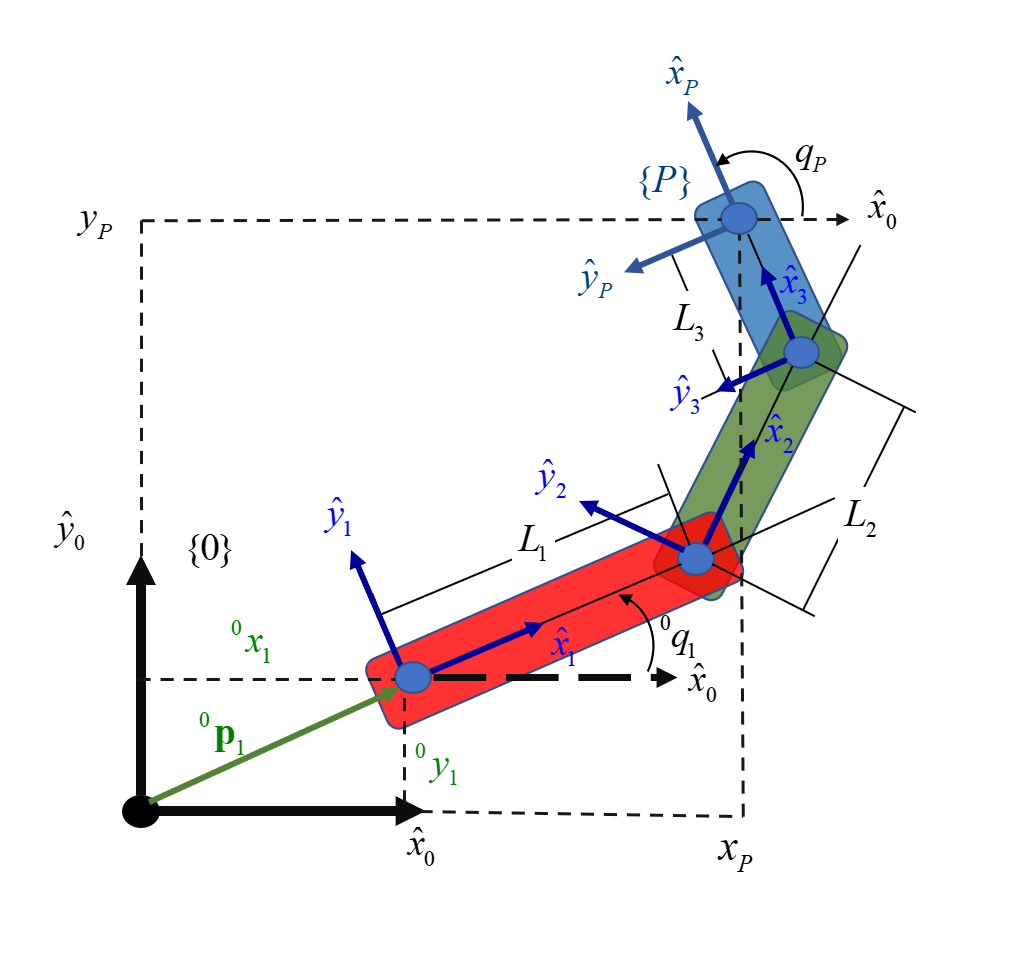

## Modelo Cinemático Directo (postura)

El modelo cinemático directo permite determinar la posición y orientación del efector final en función de las variables articulares del robot. En este caso, se realizó el análisis para un robot SCARA con tres grados de libertad rotacionales (RRR). Los pasos realizados fueron los siguientes:

**Definición de variables simbólicas y vector de configuración:**

Se definieron las variables simbólicas necesarias para representar tanto las posiciones iniciales como los ángulos articulares y longitudes de los eslabones:

syms x_O_1 y_O_1 theta_O_1 L_2 theta_1_2 L_3 theta_2_3 L_1 q
q = [theta_O_1;
    theta_1_2;
    theta_2_3]

$$q = \left(\begin{array}{c} \theta_{O,1}\\ \theta_{1,2}\\ \theta_{2,3} \end{array}\right)$$

Aquí, q representa el vector de configuración articular.

**Matrices de transformación homogénea:**

Se formularon las matrices de transformación Tij entre cada par de eslabones, siguiendo la convención de transformaciones homogéneas 2D con rotaciones alrededor del eje z y traslaciones en el plano xy:

**De la base al primer eslabón:**

T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Del primer al segundo eslabón:**

T_1_2 = Tij(L_1,0,0,0,0,theta_1_2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Del segundo al tercer eslabón:**

T_2_3 = Tij(L_2,0,0,0,0,theta_2_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Del tercer eslabón al punto P:**

T_3_P = Tij(L_3,0,0,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Multiplicación de matrices:**

La transformación total desde la base hasta el efector final se obtiene como:


$$T_O^P =T_O^1 \cdot T_1^2 \cdot T_2^3 \cdot T_3^P$$


**Simplificación del modelo:**

Al simplificar la multiplicación de matrices, se obtiene la matriz de postura final:

T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$T\_O\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

Esta expresión final describe completamente la posición y orientación del efector en el espacio, en función de las coordenadas articulares del robot.

## Modelo Cinemático Inverso (postura)

El modelo cinemático inverso permite determinar las configuraciones articulares necesarias para alcanzar una postura deseada del efector final, es decir, se parte de una posición y orientación deseadas y se calcula el conjunto de ángulos articulares que las generan.

Para este análisis se empleó el procedimiento estándar basado en el método de **"wrist-center"** y la ley de cosenos, ampliamente utilizado para manipuladores tipo 3R como el SCARA, según se describe en la literatura de Craig, Siciliano y Spong.

**Cálculo de la orientación deseada**

La orientación total del efector final se extrae a partir de la matriz de transformación homogénea utilizando la función arcotangente:

pos = T_O_P(1:2,4);  
phi = atan2(T_O_P(2,1), T_O_P(1,1))

$$phi = \text{atan2}\left(\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right),\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\right)$$

**Obtención de los ángulos articulares**

Se utilizaron las siguientes estrategias:

syms q1 q2 q3 x y phi real


**Cálculo de q2 por ley de coseno en XY**

q2p = acos((x^2 + y^2 - L_1^2 - L_2^2)/(2*L_1*L_2));  % codo arriba
q2m = -q2p;                                           % codo abajo

**Cálculo de q1 por geometría angular**

q1p = atan2(y,x) - atan2(L_2*sin(q2p), L_1 + L_2*cos(q2p));
q1m = atan2(y,x) - atan2(L_2*sin(q2m), L_1 + L_2*cos(q2m));

**Cálculo de q3 como la diferencia entre la orientación deseada y la suma de los dos primeros ángulos**

q3p = phi - q1p - q2p;
q3m = phi - q1m - q2m;

**Ensamblaje del modelo inverso**

Se obtiene el conjunto de soluciones articulares:

**Solución codo arriba:**

CInvPos  = [ q1p; q2p; q3p ];
CInvNeg = [ q1m; q2m; q3m ];
simplify(CInvPos)

$$ans = \begin{array}{l} \left(\begin{array}{c} \text{atan2}\left(y,x\right)-\sigma_{1}\\ \pi -\mathrm{acos}\left(\frac{{L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}}{2\,L_{1}\,L_{2}}\right)\\ \varphi -\pi -\text{atan2}\left(y,x\right)+\mathrm{acos}\left(\frac{{L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}}{2\,L_{1}\,L_{2}}\right)+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(L_{2}\,\sqrt{1-\frac{{\left({L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}\right)}^{2}}{4\,{L_{1}}^{2}\,{L_{2}}^{2}}},L_{1}-\frac{{L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}}{2\,L_{1}}\right) \end{array}$$

**Solución codo abajo:**

simplify(CInvNeg)

$$ans = \begin{array}{l} \left(\begin{array}{c} \text{atan2}\left(y,x\right)-\sigma_{1}\\ \mathrm{acos}\left(\frac{{L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}}{2\,L_{1}\,L_{2}}\right)-\pi \\ \varphi +\pi -\text{atan2}\left(y,x\right)-\mathrm{acos}\left(\frac{{L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}}{2\,L_{1}\,L_{2}}\right)+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\text{atan2}\left(-L_{2}\,\sqrt{1-\frac{{\left({L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}\right)}^{2}}{4\,{L_{1}}^{2}\,{L_{2}}^{2}}},L_{1}-\frac{{L_{1}}^{2}+{L_{2}}^{2}-x^{2}-y^{2}}{2\,L_{1}}\right) \end{array}$$

## Vector de postura del robot

Finalmente, se construye el vector de postura deseado, que incluye la posición y la orientación del efector en el sistema base:

xi_O_P = [T_O_P(1,4);T_O_P(2,4);theta_O_1+theta_1_2+theta_2_3]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{1,2}+\theta_{2,3}+\theta_{O,1} \end{array}\right)$$

## Modelo Cinemático Directo (velocidad)

El modelo cinemático de velocidad describe cómo las velocidades articulares del robot influyen en la velocidad lineal y angular del efector final. Para obtener este modelo, se siguen los siguientes pasos:

**Derivación del Jacobiano**

Se parte del vector de postura del efector y se calcula su derivada respecto a las variables articulares. Esto se realiza computando la matriz Jacobiana:

syms J_theta theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

J_theta 

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_O_P,[theta_O_1, theta_1_2,theta_2_3])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

Esta matriz relaciona las velocidades articulares con la velocidad del efector.

J = J_theta;

syms q_dot
q_dot

$$q\_dot = \dot{q}$$

**Definición del vector de velocidades articulares**

El vector de velocidades articulares se define como:

q_dot = [ theta_dot_O_1;
          theta_dot_1_2;
          theta_dot_2_3 ]

$$q\_dot = \left(\begin{array}{c} {\dot{\theta }}_{O,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3} \end{array}\right)$$

**Cálculo de la velocidad del efector**

La velocidad del efector se obtiene mediante la multiplicación del Jacobiano por el vector de velocidades articulares, lo cual se simplifica en la siguiente expresión:

syms xi_dot_O_P
xi_dot_O_P

$$xi\_dot\_O\_P = {\dot{\xi }}_{O,P}$$

xi_dot_O_P = simplify(J_theta * q_dot)

$$xi\_dot\_O\_P = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)+\sigma_{1}\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+\sigma_{1}\right)-L_{3}\,{\dot{\theta }}_{2,3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+L_{3}\,{\dot{\theta }}_{2,3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Esta ecuación final permite conocer la velocidad lineal del efector en el plano XY y su velocidad angular respecto al sistema base, en función de las velocidades de las articulaciones rotacionales.

## Modelo Cinemático Inverso (velocidad)

El modelo cinemático inverso de velocidad tiene como propósito determinar las velocidades articulares necesarias para lograr una velocidad deseada del efector final, conocida también como el vector de velocidad operativa.

**Inversión del Jacobiano**

Para resolver el problema inverso de velocidad, se parte de la relación directa ${\dot{\xi} }_O^P =J_{\theta } \cdot \dot{q}$

Despejando: $\dot{q} =J_{\theta }^{-1} \cdot {\dot{\xi} }_O^P$

Se calcula la matriz inversa del Jacobiano, la cual está compuesta por expresiones simbólicas que relacionan las derivadas articulares con las velocidades del efector. La matriz invertida contiene elementos complejos en función de combinaciones trigonométricas de los ángulos articulares y longitudes de los eslabones:

inv(J_theta)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$

**Cálculo de las velocidades articulares**

La expresión completa para $\dot{q}$ se obtiene al multiplicar la matriz inversa del Jacobiano por el vector ${\dot{\xi} }_O^P$. El resultado expresa cada velocidad articular como función de la velocidad deseada del efector y la configuración actual del robot:

q_dot = (inv(J_theta)) * xi_dot_O_P

Finalmente, se valida la consistencia del resultado utilizando la operación simbólica de la izquierda multiplicada por el Jacobiano invertido, mostrando que:

q_dot_sol = J \ ( xi_dot_O_P )

$$q\_dot\_sol = \left(\begin{array}{c} {\dot{\theta }}_{O,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3} \end{array}\right)$$

lo cual confirma que el modelo cinemático inverso de velocidad está correctamente definido.

## Modelo Cinemático Directo (aceleración)

El modelo cinemático de aceleración describe cómo las aceleraciones articulares del robot afectan la aceleración lineal y angular del efector final. Este modelo es fundamental para la dinámica del robot, ya que permite determinar las aceleraciones resultantes a partir de una trayectoria articular dada.

**Definición de variables**

Primero se definen las variables simbólicas correspondientes al vector de aceleraciones articulares:

syms q_ddot theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3
q_ddot

$$q\_ddot = \ddot{q}$$

q_ddot = [ theta_ddot_O_1;
           theta_ddot_1_2;
           theta_ddot_2_3 ]

$$q\_ddot = \left(\begin{array}{c} {\ddot{\theta }}_{O,1}\\ {\ddot{\theta }}_{1,2}\\ {\ddot{\theta }}_{2,3} \end{array}\right)$$

**Derivada temporal del Jacobiano**

Dado que el Jacobiano depende de las variables articulares, su derivada respecto al tiempo no es nula. Se calcula la derivada del Jacobiano usando la regla de Leibniz para derivadas de funciones vectoriales:


$$\dot{J} =\sum_{i=1}^3 \frac{\partial J}{\partial q_i }\cdot {\dot{q} }_i$$


J_dot = zeros(3,3);
for i = 1:3
  J_dot = J_dot + diff(J, q(i)) * q_dot(i);
end

**Aceleración del efector**

La aceleración del efector se calcula combinando la aceleración debida al movimiento articular y la variación del Jacobiano con el tiempo:

xi_ddot = J*q_ddot + J_dot*q_dot

Estas expresiones reflejan la complejidad del comportamiento dinámico del sistema, evidenciando cómo la aceleración del efector depende tanto de las aceleraciones como de las velocidades articulares y la geometría del manipulador.

## Modelo Cinemático Inverso (aceleración)

El modelo cinemático inverso de aceleración permite determinar las aceleraciones articulares necesarias a partir de una aceleración deseada del efector, considerando además las velocidades articulares actuales.

**Ecuación general**

Partiendo del modelo directo de aceleración:


$${\ddot{\xi} }_O^P =J\cdot \ddot{q} +\dot{J} \cdot \dot{q}$$


Se despeja el término $\ddot{q}$ para obtener el modelo inverso:


$$\ddot{q} =J^{-1} \cdot \left({\ddot{\xi} }_O^P -\dot{J} \cdot \dot{q} \right)$$


Este modelo considera dos contribuciones al vector de aceleración del efector: una derivada de la aceleración propia de las articulaciones, y otra proveniente de la variación temporal del Jacobiano.

**Implementación y simplificación**

La matriz J es invertida simbólicamente, y luego se aplica el producto con el término ${\ddot{\xi} }_O^P -\dot{J} \cdot \dot{q}$. El resultado muestra cada componente de $\ddot{q}$ en términos de las aceleraciones del efector y las derivadas articulares previas:

q_ddot = inv(J) * (xi_ddot - (J_dot * q_dot))

**Solución computacional**

La solución simbólica se expresa finalmente usando la notación de división por izquierda:

q_ddot_sol = J \ ( xi_ddot - J_dot*q_dot )

$$q\_ddot\_sol = \left(\begin{array}{c} {\ddot{\theta }}_{O,1}\\ {\ddot{\theta }}_{1,2}\\ {\ddot{\theta }}_{2,3} \end{array}\right)$$

Esto permite resolver el sistema lineal de manera eficiente, obteniendo el vector de aceleraciones articulares requerido para seguir una trayectoria con aceleración definida en el espacio del efector.

## Modelo Dinámico por Ecuaciones de Eüler-Lagrange

Para obtener el modelo dinámico del robot SCARA, se utiliza el enfoque energético basado en la formulación de **Euler-Lagrange**, el cual permite derivar las ecuaciones del movimiento a partir del análisis de energías cinética y potencial de cada eslabón del sistema.

**Energía cinética**

La energía cinética total de un eslabón se calcula con la expresión:


$$k_{i} = \frac{m_{i}}{2} \mathbf{v}_{C_{i}}^T \mathbf{v}_{C_{i}} + \frac{1}{2} \mathbf{\omega}_{C_{i}}^T \mathbf{I}_{C_{i}} \mathbf{\omega}_{C_{i}}


$$


Esta ecuación se aplicará posteriormente de la siguiente manera:

**Velocidad del centro de masa del primer eslabón**

Se define simbólicamente la posición del centro de masa del primer eslabón en su propio marco:

syms x_1_C1 theta_dot_O_1

v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

$$v\_C1\_C1 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$

Luego, se expresa esta velocidad en el sistema base mediante una transformación adecuada que considera la rotación debida al ángulo:

v_O_C1 = [-x_1_C1*sin(theta_O_1)*theta_dot_O_1;x_1_C1*cos(theta_O_1)*theta_dot_O_1;0]

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

**Energía cinética del eslabón 1**

El producto escalar de la velocidad consigo misma proporciona la energía cinética translacional:

transpose(v_C1_C1)*v_C1_C1

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

simplify(transpose(v_O_C1)*v_O_C1)

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

Este resultado indica que la energía cinética depende cuadráticamente de la velocidad angular y de la distancia del centro de masa al eje de rotación. Aún no se ha incluido la contribución rotacional, pero esta será añadida posteriormente al ensamblar el Lagrangiano completo.

## Cálculo de la posición de los centros de masa

Para la formulación dinámica del manipulador, es esencial conocer la posición de los centros de masa de cada uno de sus eslabones en el sistema de referencia base. Este cálculo se realiza utilizando matrices de transformación homogénea que permiten transformar coordenadas locales de los centros de masa a coordenadas globales.

**Definición de marcos de referencia intermedios**

Para cada eslabón, se definió la posición del centro de masa en su propio marco de referencia. Se utilizaron transformaciones homogéneas de la forma:


$$T_i^{C_i } =T_{\textrm{ij}} \left(x_i C_i ,0,0,0,0,0,0\right)$$


Estas matrices representan una traslación simple a lo largo del eje x, correspondiente a la ubicación del centro de masa respecto al origen del eslabón.

**Transformaciones al sistema base**

A continuación, se multiplicaron las matrices correspondientes para obtener la posición del centro de masa en el sistema base:

**Eslabón 1:**

syms x_1_C1 x_2_C2 x_3_C3
T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C1 = T_O_1*T_1_C1

$$T\_O\_C1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Eslabón 2:**

T_2_C2 = Tij(x_2_C2,0,0,0,0,0)

$$T\_2\_C2 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{2,\mathrm{C2}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C2 = T_O_1*T_1_2*T_2_C2

$$T\_O\_C2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)-\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) & 0 & x_{O,1}+x_{2,\mathrm{C2}}\,\sigma_{1}+L_{1}\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2} & \sigma_{1} & 0 & y_{O,1}+x_{2,\mathrm{C2}}\,\sigma_{2}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

**Eslabón 3:**

T_3_C3 = Tij(x_3_C3,0,0,0,0,0)

$$T\_3\_C3 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{3,\mathrm{C3}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_O_C3 = T_O_1*T_1_2*T_2_3*T_3_C3

$$T\_O\_C3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{2,3}\right)\,\sigma_{4}-\sin\left(\theta_{2,3}\right)\,\sigma_{3} & 0 & x_{O,1}+L_{2}\,\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{1}\\ \sigma_{2} & \sigma_{1} & 0 & y_{O,1}+L_{2}\,\sigma_{4}+L_{1}\,\sin\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,3}\right)\,\sigma_{3}-\sin\left(\theta_{2,3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(\theta_{2,3}\right)\,\sigma_{4}+\sin\left(\theta_{2,3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

#### Vectores de posición de los centros

p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]

$$p\_O\_C1 = \left(\begin{array}{c} x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

p_O_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

$$p\_O\_C2 = \left(\begin{array}{c} x_{O,1}+x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

p_O_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

$$p\_O\_C3 = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

**Aplicación**

Estos vectores de posición permiten calcular las energías cinéticas y potenciales de cada eslabón en el sistema base, fundamentales para la formulación dinámica mediante el enfoque de Euler-Lagrange. Además, representan las trayectorias que siguen los centros de masa durante el movimiento del robot, siendo clave en el análisis de equilibrio y dinámica.

## Cálculo de las velocidades

Para evaluar la energía cinética de cada eslabón del robot SCARA, se requiere conocer la velocidad lineal de su centro de masa, expresada en el sistema de referencia base. Estas velocidades se obtienen diferenciando los vectores de posición previamente calculados.

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

**Procedimiento**

Se aplica la regla de la cadena para derivadas vectoriales respecto al tiempo, considerando las derivadas parciales respecto a las variables articulares y multiplicando por sus velocidades respectivas:

**Velocidad del centro de masa del eslabón 1:**

v_O_C1 = diff(p_O_C1,theta_O_1)*theta_dot_O_1+diff(p_O_C1,theta_1_2)*theta_dot_1_2+diff(p_O_C1,theta_2_3)*theta_dot_2_3

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

**Velocidad del centro de masa del eslabón 2:**

v_O_C2 = diff(p_O_C2,theta_O_1)*theta_dot_O_1+diff(p_O_C2,theta_1_2)*theta_dot_1_2+diff(p_O_C2,theta_2_3)*theta_dot_2_3

$$v\_O\_C2 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ 0 \end{array}\right)$$

**Velocidad del centro de masa del eslabón 3:**

v_O_C3 = diff(p_O_C3,theta_O_1)*theta_dot_O_1+diff(p_O_C3,theta_1_2)*theta_dot_1_2+diff(p_O_C3,theta_2_3)*theta_dot_2_3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Estas velocidades se utilizarán en el cálculo de la energía cinética de cada eslabón. Este cálculo constituye uno de los pasos fundamentales para la obtención del Lagrangiano del sistema, el cual será utilizado en la derivación de las ecuaciones del movimiento.

## Cálculo de la velocidades angulares

En la dinámica de robots, las velocidades angulares de los eslabones son necesarias para calcular la energía cinética rotacional. Estas se obtienen mediante un proceso de propagación, a partir del sistema base y utilizando las matrices de rotación entre eslabones.

**Propagación de la velocidad angular**

La propagación se realiza mediante la ecuación recursiva:


$$\omega_i =R_i^{i-1} \cdot \omega_{i-1} +n_i \cdot {\dot{\theta} }_i$$


syms omega_1_1 omega_2_2 omega_3_3

**Eslabón 1:**

omega_1_1

$$omega\_1\_1 = \omega_{1,1}$$

omega_O_O = [0;0;0]

omega_O_O =      0
     0
     0


n_1_1 = [0;0;1]

n_1_1 =      0
     0
     1


R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_1_O = transpose(R_O_1)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%Ecuación de propagación
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

**Eslabón 2:**

omega_2_2

$$omega\_2\_2 = \omega_{2,2}$$

n_2_2 = [0;0;1]

n_2_2 =      0
     0
     1


R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_2_1 = transpose(R_1_2)

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%Ecuación de propagación
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$

**Eslabón 3:**

omega_3_3

$$omega\_3\_3 = \omega_{3,3}$$

n_3_3 = [0;0;1]

n_3_3 =      0
     0
     1


R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_3_2 = transpose(R_2_3)

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%Ecuación de propagación
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

v_O_C3

$$v\_O\_C3 = \begin{array}{l} \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,\left(\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)-{\dot{\theta }}_{1,2}\,\left(\sigma_{1}+\sigma_{3}\right)-{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Estas velocidades angulares se utilizan en la formulación de la energía cinética rotacional para cada eslabón.

## Definición de los elementos de inercia 

Para la formulación dinámica completa mediante el método de Euler-Lagrange, se requiere modelar no solo las velocidades lineales y angulares de los cuerpos, sino también sus propiedades inerciales. En este caso, se definen las matrices de inercia de los tres eslabones del robot SCARA, expresadas en sus respectivos sistemas de referencia centrados en el centro de masa.

syms g I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3

**Vector de gravedad**

Primero, se define el vector de gravedad que influirá en la energía potencial del sistema:

g_v = [0;-g;0]

$$g\_v = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$

**Matrices de inercia**

Las matrices de inercia para los tres eslabones se asumen diagonales, una simplificación válida para cuerpos simétricos y eslabones delgados. Se definen como:

**Eslabón 1:**

I_C1 = [I_xx1,0,0;0,I_yy1,0;0,0,I_zz1]

$$I\_C1 = \left(\begin{array}{ccc} I_{\mathrm{xx1}} & 0 & 0\\ 0 & I_{\mathrm{yy1}} & 0\\ 0 & 0 & I_{\mathrm{zz1}} \end{array}\right)$$

**Eslabón 2:**

I_C2 = [I_xx2,0,0;0,I_yy2,0;0,0,I_zz2]

$$I\_C2 = \left(\begin{array}{ccc} I_{\mathrm{xx2}} & 0 & 0\\ 0 & I_{\mathrm{yy2}} & 0\\ 0 & 0 & I_{\mathrm{zz2}} \end{array}\right)$$

**Eslabón 3:**

I_C3 = [I_xx3,0,0;0,I_yy3,0;0,0,I_zz3]

$$I\_C3 = \left(\begin{array}{ccc} I_{\mathrm{xx3}} & 0 & 0\\ 0 & I_{\mathrm{yy3}} & 0\\ 0 & 0 & I_{\mathrm{zz3}} \end{array}\right)$$

Estas matrices se usarán en la expresión de la energía cinética rotacional de cada cuerpo. Una vez definidas las matrices de inercia, estas se integran en el cálculo del Lagrangiano del sistema junto con los términos de energía cinética translacional y energía potencial, permitiendo así derivar las ecuaciones de movimiento del sistema completo.

## Cálculo del Lagrangeano

El Lagrangiano del sistema, denotado como $L$, se define como la diferencia entre la energía cinética total K y la energía potencial total U.

syms m_1 m_2 m_3

#### Energía cinética de cada uno de los cuerpos

La energía cinética de cada eslabón se compone de dos partes: la **energía cinética traslacional** y la **rotacional**, calculadas como:

**Eslabón 1:**

k_1 = simplify((m_1/2)*transpose(v_O_C1)*v_O_C1+(1/2)*transpose(omega_1_1)*I_C1*omega_1_1)

$$k\_1 = \frac{{{\dot{\theta }}_{O,1}}^{2}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)}{2}$$

**Eslabón 2:**

k_2 = simplify((m_2/2)*transpose(v_O_C2)*v_O_C2+(1/2)*transpose(omega_2_2)*I_C2*omega_2_2)

$$k\_2 = \frac{m_{2}\,{L_{1}}^{2}\,{{\dot{\theta }}_{O,1}}^{2}}{2}+m_{2}\,\cos\left(\theta_{1,2}\right)\,L_{1}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}+m_{2}\,\cos\left(\theta_{1,2}\right)\,L_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{2,\mathrm{C2}}+\frac{m_{2}\,{{\dot{\theta }}_{1,2}}^{2}\,{x_{2,\mathrm{C2}}}^{2}}{2}+\frac{I_{\mathrm{zz2}}\,{{\dot{\theta }}_{1,2}}^{2}}{2}+m_{2}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}\,{\dot{\theta }}_{O,1}+\frac{m_{2}\,{{\dot{\theta }}_{O,1}}^{2}\,{x_{2,\mathrm{C2}}}^{2}}{2}+\frac{I_{\mathrm{zz2}}\,{{\dot{\theta }}_{O,1}}^{2}}{2}$$

**Eslabón 3:**

k_3 = simplify((m_3/2)*transpose(v_O_C3)*v_O_C3+(1/2)*transpose(omega_3_3)*I_C3*omega_3_3)

$$k\_3 = \begin{array}{l} \frac{m_{3}\,{\left({\dot{\theta }}_{O,1}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\right)}^{2}}{2}+I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

#### Cálculo de la energía potencial de cada cuerpo

La energía potencial de cada eslabón se calcula como:


$$U_i =-m_i g_v^T \cdot p_{C_i }$$


Con el vector de gravedad $g_v ={\lbrack 0,-g,0\rbrack }^T$, la energía potencial se expresa según la componente Y de la posición de cada centro de masa:

**Eslabón 1:**

u_1 = -m_1*transpose(p_O_C1)*g_v

$$u\_1 = g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)$$

**Eslabón 2:**

u_2 = -m_2*transpose(p_O_C2)*g_v

$$u\_2 = g\,m_{2}\,\left(y_{O,1}+x_{2,\mathrm{C2}}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)$$

**Eslabón 3:**

u_3 = -m_3*transpose(p_O_C3)*g_v

$$u\_3 = g\,m_{3}\,\left(y_{O,1}+x_{3,\mathrm{C3}}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)\right)$$

## Lagrangeano total

Una vez sumadas todas las energías cinéticas y potenciales, se obtiene el Lagrangeano como:

La = (k_1+k_2+k_3)-(u_1+u_2+u_3)

## Cálculo de los pares

Para obtener las ecuaciones del movimiento del robot SCARA, se aplican las **ecuaciones de Euler-Lagrange** sobre el Lagrangiano previamente calculado.

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

**Par para la articulación 1:**

Se calcula derivando la expresión del Lagrangiano respecto a ${\dot{\theta} }_{0_1 }$, y luego se deriva temporalmente considerando la dependencia de todas las velocidades articulares:

D_theta1 = diff(La,theta_dot_O_1)

$$D\_theta1 = \begin{array}{l} I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{O,1}+{\dot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+I_{\mathrm{zz1}}\right)+\frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,\sigma_{1}\,\left({\dot{\theta }}_{O,1}\,\sigma_{1}+{\dot{\theta }}_{1,2}\,\left(\sigma_{3}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,\sigma_{2}\,\left({\dot{\theta }}_{O,1}\,\sigma_{2}+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{6}\right)+{L_{1}}^{2}\,m_{2}\,{\dot{\theta }}_{O,1}+L_{1}\,m_{2}\,{\dot{\theta }}_{1,2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)+2\,L_{1}\,m_{2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{6}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

tao_1 = diff(D_theta1,theta_O_1)*theta_dot_O_1 + diff(D_theta1,theta_1_2)*theta_dot_1_2 + diff(D_theta1,theta_2_3)*theta_dot_2_3 + diff(D_theta1,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta1,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta1,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_O_1)

**Par para la articulación 2:**

Esta ecuación es análoga a la anterior, pero ahora considera la dependencia en $\theta_{1_2 }$ y ${\dot{\theta} }_{1_2 }$. También se incorporan los efectos de las articulaciones anteriores debido a la estructura en serie del robot:

D_theta2 = diff(La,theta_dot_1_2)

$$D\_theta2 = \begin{array}{l} I_{\mathrm{zz2}}\,{\dot{\theta }}_{1,2}+I_{\mathrm{zz2}}\,{\dot{\theta }}_{O,1}+\frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{2}\,{\dot{\theta }}_{1,2}\,{x_{2,\mathrm{C2}}}^{2}+m_{2}\,{\dot{\theta }}_{O,1}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)\,\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\right)+m_{3}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\left({\dot{\theta }}_{O,1}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\right)+L_{1}\,m_{2}\,{\dot{\theta }}_{O,1}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

tao_2 = diff(D_theta2,theta_O_1)*theta_dot_O_1 + diff(D_theta2,theta_1_2)*theta_dot_1_2 + diff(D_theta2,theta_2_3)*theta_dot_2_3 + diff(D_theta2,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta2,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta2,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_1_2)

**Par para la articulación 3:**

El tercer par está influenciado principalmente por la masa y aceleración del tercer eslabón, pero también por todos los términos combinados de velocidades, posiciones y sus respectivas derivadas, debido a la propagación de efectos dinámicos desde las articulaciones anteriores.

D_theta3 = diff(La,theta_dot_2_3)

$$D\_theta3 = \begin{array}{l} \frac{I_{\mathrm{zz3}}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)}{2}+I_{\mathrm{zz3}}\,\left(\frac{{\dot{\theta }}_{1,2}}{2}+\frac{{\dot{\theta }}_{2,3}}{2}+\frac{{\dot{\theta }}_{O,1}}{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left({\dot{\theta }}_{O,1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)+{\dot{\theta }}_{1,2}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left({\dot{\theta }}_{O,1}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+{\dot{\theta }}_{1,2}\,\left(\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+{\dot{\theta }}_{2,3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

tao_3 = diff(D_theta3,theta_O_1)*theta_dot_O_1 + diff(D_theta3,theta_1_2)*theta_dot_1_2 + diff(D_theta3,theta_2_3)*theta_dot_2_3 + diff(D_theta3,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta3,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta3,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_2_3)

**Vector de pares resultante**

Finalmente, se obtiene el vector de pares requerido para lograr el movimiento deseado:

tao = [tao_1;tao_2;tao_3]

Este conjunto de ecuaciones puede usarse tanto para **control de trayectoria** como para simulaciones dinámicas, ya que describe completamente la dinámica inversa del robot SCARA RRR.

## Cálculo de la matriz de inercia

La **matriz de inercia** describe cómo se relacionan las aceleraciones articulares con las fuerzas/torques requeridos para generarlas, en ausencia de efectos de Coriolis, centrífugos y gravitacionales. Es uno de los términos clave de la ecuación dinámica general:


$$\tau =M\left(\theta \right)\ddot{q} +C\left(\theta \dot{,q} \right)\dot{q} +G\left(\theta \right)$$


Se obtiene simbólicamente extrayendo el término que multiplica a cada aceleración articular� en el vector de torques. Esto se logra evaluando $\tau$ con solo una aceleración activa a la vez:

M1 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[1,0,0,0,0,0,0])

$$M1 = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{zz1}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,{\sigma_{1}}^{2}+{L_{1}}^{2}\,m_{2}+m_{3}\,{\sigma_{2}}^{2}+m_{1}\,{x_{1,\mathrm{C1}}}^{2}+m_{2}\,{x_{2,\mathrm{C2}}}^{2}+2\,L_{1}\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}\right)\\ m_{2}\,{x_{2,\mathrm{C2}}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,\left(\sigma_{3}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\sigma_{1}+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}\right)\,\sigma_{2}\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\,\sigma_{1}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{6}\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\\ \sigma_{2}=x_{3,\mathrm{C3}}\,\sigma_{6}+\sigma_{5}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{6}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

M2 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,1,0,0,0,0,0])

$$M2 = \begin{array}{l} \left(\begin{array}{c} m_{2}\,{x_{2,\mathrm{C2}}}^{2}+L_{1}\,m_{2}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{3}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)\\ I_{\mathrm{zz2}}+I_{\mathrm{zz3}}+m_{2}\,{x_{2,\mathrm{C2}}}^{2}+m_{3}\,{\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)}^{2}+m_{3}\,{\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right)}^{2}\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{4}\,\left(\sigma_{2}+x_{3,\mathrm{C3}}\,\sigma_{4}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{3}\,\left(x_{3,\mathrm{C3}}\,\sigma_{3}+\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

M3 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,1,0,0,0,0])

$$M3 = \begin{array}{l} \left(\begin{array}{c} I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left(\sigma_{4}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}+L_{1}\,\sin\left(\theta_{O,1}\right)\right)\\ I_{\mathrm{zz3}}+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{2}\,\left(\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{2}\right)+m_{3}\,x_{3,\mathrm{C3}}\,\sigma_{1}\,\left(x_{3,\mathrm{C3}}\,\sigma_{1}+\sigma_{3}\right)\\ m_{3}\,{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{2}}^{2}+m_{3}\,{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{1}}^{2}+I_{\mathrm{zz3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{3}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{4}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

**Forma final**

M_theta = collect([M1 M2 M3],[m_1,m_2,m_3])

$$M\_theta = \begin{array}{l} \left(\begin{array}{ccc} {x_{1,\mathrm{C1}}}^{2}\,m_{1}+\left({L_{1}}^{2}+2\,\cos\left(\theta_{1,2}\right)\,L_{1}\,x_{2,\mathrm{C2}}+{x_{2,\mathrm{C2}}}^{2}\right)\,m_{2}+\left({\sigma_{4}}^{2}+{\sigma_{5}}^{2}\right)\,m_{3}+I_{\mathrm{zz1}}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & {x_{2,\mathrm{C2}}}^{2}\,m_{2}+\left({\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)}^{2}+{\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)}^{2}\right)\,m_{3}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}} & \sigma_{3}\\ \sigma_{2} & \sigma_{3} & \left({x_{3,\mathrm{C3}}}^{2}\,{\sigma_{6}}^{2}+{x_{3,\mathrm{C3}}}^{2}\,{\sigma_{8}}^{2}\right)\,m_{3}+I_{\mathrm{zz3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left({x_{2,\mathrm{C2}}}^{2}+L_{1}\,\cos\left(\theta_{1,2}\right)\,x_{2,\mathrm{C2}}\right)\,m_{2}+\left(\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)\,\sigma_{4}+\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)\,\sigma_{5}\right)\,m_{3}+I_{\mathrm{zz2}}+I_{\mathrm{zz3}}\\ \sigma_{2}=\left(x_{3,\mathrm{C3}}\,\sigma_{6}\,\sigma_{4}+x_{3,\mathrm{C3}}\,\sigma_{8}\,\sigma_{5}\right)\,m_{3}+I_{\mathrm{zz3}}\\ \sigma_{3}=\left(x_{3,\mathrm{C3}}\,\sigma_{6}\,\left(\sigma_{7}+x_{3,\mathrm{C3}}\,\sigma_{6}\right)+x_{3,\mathrm{C3}}\,\sigma_{8}\,\left(x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}\right)\right)\,m_{3}+I_{\mathrm{zz3}}\\ \sigma_{4}=\sigma_{7}+L_{1}\,\cos\left(\theta_{O,1}\right)+x_{3,\mathrm{C3}}\,\sigma_{6}\\ \sigma_{5}=x_{3,\mathrm{C3}}\,\sigma_{8}+\sigma_{9}+L_{1}\,\sin\left(\theta_{O,1}\right)\\ \sigma_{6}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{7}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ \sigma_{8}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{9}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

M = M_theta;

## Cálculo del vector de pares de Coriolis

Una vez obtenida la matriz de inercia, se puede completar el modelo dinámico general del manipulador:


$$\tau =M\left(\theta \right)\ddot{q} +C\left(\theta \dot{,q} \right)\dot{q} +G\left(\theta \right)$$


**Cálculo del vector de Coriolis **${\mathit{\mathbf{V}}}_{\theta }$**�**

Se obtiene anulando las aceleraciones articulares ${\ddot{q} }_i =0$, manteniendo las velocidades ${\dot{q} }_i$ activas. Es decir, se evalúa el vector de torques $\tau$ únicamente con las velocidades presentes.

V_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,0])

Este vector contiene términos cuadráticos en las velocidades articulares y representa las fuerzas necesarias para compensar los efectos de Coriolis y centrífugos en el movimiento.

**Cálculo del vector de gravedad **${\mathit{\mathbf{G}}}_{\theta }$**�**

Se calcula evaluando $\tau$ únicamente con el parámetro gravitacional activo, es decir, con ${\ddot{q} }_i =0$, ${\dot{q} }_i =0$, y $g\not= 0$.

G_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,0,0,0,g])

$$G\_theta = \begin{array}{l} \left(\begin{array}{c} g\,m_{3}\,\left(\sigma_{2}+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{1}\right)+g\,m_{2}\,\left(x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)\right)+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ g\,m_{3}\,\left(\sigma_{2}+\sigma_{1}\right)+g\,m_{2}\,x_{2,\mathrm{C2}}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\\ g\,m_{3}\,x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{3,\mathrm{C3}}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right) \end{array}$$

Este vector representa los torques que deben ser aplicados en cada articulación para compensar exclusivamente el efecto del peso del robot en su configuración actual.

## Modelo Dinámico Directo (completo)

Con estos tres componentes se completa la ecuación de movimiento del robot SCARA RRR:


$$\tau =M\left(\theta \right)\ddot{q} +V_{\theta } +G\left(\theta \right)$$


tau = simplify( M*q_ddot + V_theta + G_theta )

Este modelo puede ser implementado en simuladores, controladores adaptativos o algoritmos de planificación dinámica de trayectorias.

## Cálculo del modelo Dinámico Inverso

El **modelo dinámico inverso** consiste en despejar las aceleraciones articulares� a partir de un conjunto de torques deseados, lo que permite simular el comportamiento del sistema ante una entrada de fuerza/control:


$$\ddot{q} =M{\left(\theta \right)}^{-1} \left(\tau -V_{\theta } -G_{\theta } \right)$$


q_ddot_sol = simplify( inv(M_theta)*( tau - V_theta - G_theta ) )

$$q\_ddot\_sol = \left(\begin{array}{c} {\ddot{\theta }}_{O,1}\\ {\ddot{\theta }}_{1,2}\\ {\ddot{\theta }}_{2,3} \end{array}\right)$$

Este vector representa las aceleraciones angulares de las articulaciones del robot, como respuesta a un conjunto de torques aplicados, y es esencial en simulaciones dinámicas en tiempo real, validación de modelos, y diseño de controladores basados en la dinámica.

## **Conclusiones**

#### **Modelos Cinemáticos**

- Se derivaron con éxito las fórmulas de posición $\left(x,y,\phi \right)$, velocidad $\left(\dot{\xi} =J\left(q\right)\dot{q} \right)$ y aceleración $\left(\ddot{\xi} =J*\left(\ddot{q} \right)+\dot{J*} \left(\dot{q} \right)\right)$ del efector final en función de los ángulos articulares.

- La cinemática inversa proporciona dos configuraciones (“codo-arriba” y “codo-abajo”) que satisfacen la posición y orientación deseadas, mediante la ley de cosenos y geometría angular.

#### **Modelos Dinámicos**

- A partir del Lagrangeano $\Gamma =k-u$ se obtuvieron la matriz de inercia $M\left(q\right)$, el término de Coriolis $C\left(q,\dot{q} \right)\dot{q}$ y el vector gravitacional $g\left(q\right)$.

- El modelo dinámico directo $\tau =M\ddot{q} +C\dot{q} +g$ permite calcular los pares necesarios para cualquier perfil de movimiento.

- La forma inversa $\ddot{q} =M^{-1} \left(\tau -C\dot{q} -g\right)$ facilita el diseño basado en aceleraciones deseadas.

En resumen, el trabajo realizado demuestra que el modelado cinemático y dinámico del robot SCARA puede abordarse de manera sistemática, desde la posición hasta la dinámica inversa. Esta base teórica permite extender el análisis a tareas de control y simulación, y eventualmente a la implementación en robots reales.

#### **Validación de la Hipótesis**

Las expresiones obtenidas cumplen coherentemente con los principios teóricos y verifican la hipótesis de que los métodos empleados conforman un marco completo para el análisis y control de manipuladores SCARA.

En conjunto, estos resultados demuestran que el método empleado es fiable y proporciona un punto de partida claro para diseñar y poner en marcha algoritmos de control y de simulación. Gracias a la sencillez y coherencia de los modelos obtenidos, los ingenieros podrán implementar y probar fácilmente estrategias de control tanto en entornos de investigación como en procesos industriales reales.